clear; close all;
rng("default");
tic

load('mitdb_dataset.mat');  % Assuming 'ecg' is loaded here
load('em_noise.mat');
Fs = 360;  % Sampling Frequency
numComponents = 15;
start_time = 330; 
end_time = 350;
signal_index = 3;  % Index of the ECG signal you want to use

% Using the specific ECG signal
training_ecg = ecg{signal_index};  % Directly use the signal from the cell array
testing_ecg = ecg{signal_index};  % Same here, but in a real scenario you'd separate testing data differently

% Noise levels for EM noise and Gaussian noise dB levels
em_noise_levels = [0.1, 0.2, 0.3];
gaussian_db_levels = [12, 6, 2];

% Initialize performance metrics storage
num_cases = length(em_noise_levels) + length(gaussian_db_levels);
mses = zeros(num_cases, 1);
snr_imp = zeros(num_cases, 1);
prd = zeros(num_cases, 1);
reconstructed_signals_EM = cell(length(em_noise_levels), 1);
reconstructed_signals_Gaus = cell(length(gaussian_db_levels), 1);

% Testing with EM noise
for j = 1:length(em_noise_levels)
    noise_scaling_factor = em_noise_levels(j);
    noise = em_noise * noise_scaling_factor;
    orig_sig = training_ecg(start_time * Fs : end_time * Fs) - mean(training_ecg(start_time * Fs : end_time * Fs));
    orig_sig_plus_noise = orig_sig + noise(start_time * Fs : end_time * Fs);
    
    % Reshape the signal for ICA
    [reconstructed_signal, mses(j), snr_imp(j), prd(j)] = performICA(orig_sig', orig_sig_plus_noise', numComponents);
    reconstructed_signals_EM{j} = reconstructed_signal;
end


% Testing with Gaussian noise
for k = 1:length(gaussian_db_levels)
    db_level = gaussian_db_levels(k);
    orig_sig = training_ecg(start_time * Fs : end_time * Fs) - mean(training_ecg(start_time * Fs : end_time * Fs));
    
    % Use the helper function to create noisy signal
    [orig_sig_plus_noise_gaus, targetNoiseSigma] = createSignalPlusNoise(orig_sig, db_level);
    
    % Reshape the signal for ICA
    [reconstructed_signal_Gaus, mses(length(em_noise_levels) + k), snr_imp(length(em_noise_levels) + k), prd(length(em_noise_levels) + k)] = performICA(orig_sig', orig_sig_plus_noise_gaus', numComponents);
    reconstructed_signals_Gaus{k} = reconstructed_signal_Gaus;
end
toc

Elapsed time is 490.047196 seconds.


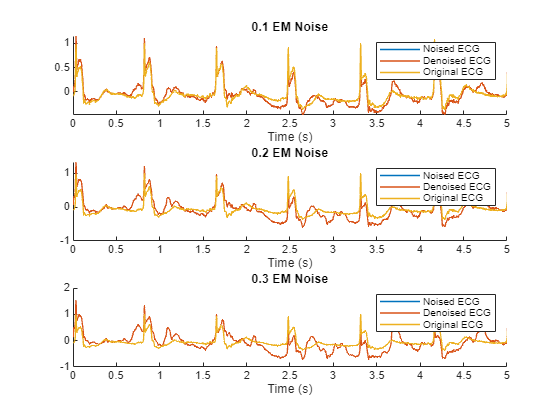


%% Plot Results for ICA
figure;
for j = 1:length(em_noise_levels)
    subplot(3,1,j);
    orig_sig = testing_ecg(start_time*Fs:end_time*Fs) - mean(testing_ecg(start_time*Fs:end_time*Fs));
    orig_sig_plus_noise = orig_sig + em_noise(start_time*Fs:end_time*Fs) * em_noise_levels(j);
    den_sig = reconstructed_signals_EM{j};
    
    t = (1:length(orig_sig))/Fs;
    hold on;
    plot(t, orig_sig_plus_noise, 'LineWidth', 1);
    plot(t, den_sig, 'LineWidth', 1);
    plot(t, orig_sig, 'LineWidth', 1);
    xlim([0, 5]);
    xlabel('Time (s)');
    legend('Noised ECG', 'Denoised ECG', 'Original ECG');
    title(sprintf('%0.1f EM Noise', em_noise_levels(j)));
end

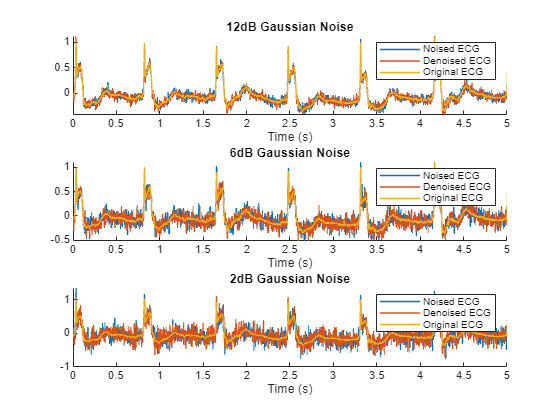


% Plot Results for ICA with Gaussian noise
figure;
for k = 1:length(gaussian_db_levels)
    subplot(3, 1, k);
    orig_sig = testing_ecg(start_time * Fs : end_time * Fs) - mean(testing_ecg(start_time * Fs : end_time * Fs));
    [orig_sig_plus_noise, ~] = createSignalPlusNoise(orig_sig, gaussian_db_levels(k));
    den_sig = reconstructed_signals_Gaus{k};
    
    t = (1:length(orig_sig)) / Fs;
    hold on;
    plot(t, orig_sig_plus_noise, 'LineWidth', 1);
    plot(t, den_sig, 'LineWidth', 1);
    plot(t, orig_sig, 'LineWidth', 1);
    xlim([0, 5]);
    xlabel('Time (s)');
    legend('Noised ECG', 'Denoised ECG', 'Original ECG');
    title(sprintf('%ddB Gaussian Noise', gaussian_db_levels(k)));
end

function [reconstructed_signal, mse, snr, prd] = performICA(original_signal, noised_signal, numComponents)
    Z = noised_signal(:);
    [Zica, W, T, mu] = kICA(Z, numComponents);  % Perform ICA

    % Calculate kurtosis and entropy for each component
    componentKurtosis = kurtosis(Zica');
    entropies = -sum(Zica .* log(abs(Zica) + eps), 1);

    % Define thresholds for kurtosis and entropy
    thresholdKurtosis = prctile(componentKurtosis, 85);
    thresholdEntropy = prctile(entropies, 70);
    noiseIndicesKurt = find(componentKurtosis > thresholdKurtosis);
    noiseIndicesEntropy = find(entropies > thresholdEntropy);
    noiseIndices = unique([noiseIndicesKurt noiseIndicesEntropy]);

    % Zero out noise components
    Zica(noiseIndices, :) = 0;

    % Reconstruct the signal
    reconstructed_signal = T \ (W(:,1:numComponents) * Zica(1:numComponents,:));
    reconstructed_signal = reconstructed_signal' + mu';  % Adding mean after transposing

    % Calculate MSE, SNR Improvement, and PRD
    mse = mean((original_signal - reconstructed_signal).^2);
    snr = 10 * log10(sum((noised_signal - original_signal).^2) / sum((reconstructed_signal - original_signal).^2));
    prd = 100 * sqrt(sum((reconstructed_signal - original_signal).^2) / sum(original_signal.^2));

    return
end

function [noisySig,targetNoiseSigma] = createSignalPlusNoise(signal,targetSNR_dB)
% function [noisySig,targetNoiseSigma] = createSignalPlusNoise(signal,targetSNR_dB)
% this is a "helper function" to add white Gaussian noise to a signal, for
% testing denoising performance

n = length(signal);

targetSNR_lin = lin10(targetSNR_dB);

signalPower = var(signal);

targetNoiseSigma = sqrt(signalPower/targetSNR_lin);

noise = randn(size(signal)) * targetNoiseSigma;

noisySig = signal+noise;

% check 
noisePower = mean(noise.^2);
%sprintf('Sig pow = %2.2f dB, Noise pow = %2.2f dB, SNR = %2.2f',db10(signalPower),db10(noisePower), db10(signalPower/noisePower))
return
end

function x = lin10(xdb)
%function x = lin10(xdb)
%xdb = 10*log10(abs(x)+eps);
x=10.^(xdb./10);
return
end

